load("RawPropulsionData.mat")

HoverThrust = 0.645*9.81/4 % N

HoverThrust = 1.5819

Throttles = 10:1:100;

KV1950.b2_i30.Current = zeros(100,1);
KV1950.b3_i20.Current = zeros(100,1);
KV1950.b3_i30.Current = zeros(100,1);
KV1950.b3_i37.Current = zeros(100,1);

KV2550.b2_i30.Current = zeros(100,1);
KV2550.b3_i20.Current = zeros(100,1);
KV2550.b3_i30.Current = zeros(100,1);
KV2550.b3_i37.Current = zeros(100,1);


KV1950.b2_i30.Thrust = zeros(100,1);
KV1950.b3_i20.Thrust = zeros(100,1);
KV1950.b3_i30.Thrust = zeros(100,1);
KV1950.b3_i37.Thrust = zeros(100,1);

KV2550.b2_i30.Thrust = zeros(100,1);
KV2550.b3_i20.Thrust = zeros(100,1);
KV2550.b3_i30.Thrust = zeros(100,1);
KV2550.b3_i37.Thrust = zeros(100,1);


KV1950.b2_i30.Torque = zeros(100,1);
KV1950.b3_i20.Torque = zeros(100,1);
KV1950.b3_i30.Torque = zeros(100,1);
KV1950.b3_i37.Torque = zeros(100,1);

KV2550.b2_i30.Torque = zeros(100,1);
KV2550.b3_i20.Torque = zeros(100,1);
KV2550.b3_i30.Torque = zeros(100,1);
KV2550.b3_i37.Torque = zeros(100,1);

for i=Throttles
    KV1950.b2_i30.Current(i) = mean([Raw.KV1950.b2_i30.ThrustFull(Raw.KV1950.b2_i30.ThrustFull(:,4)==i,3); Raw.KV1950.b2_i30.ThrustHover(Raw.KV1950.b2_i30.ThrustHover(:,4)==i,3); Raw.KV1950.b2_i30.Torque(Raw.KV1950.b2_i30.Torque(:,4)==i,3)]);
    KV1950.b3_i20.Current(i) = mean([Raw.KV1950.b3_i20.ThrustFull(Raw.KV1950.b3_i20.ThrustFull(:,4)==i,3); Raw.KV1950.b3_i20.ThrustHover(Raw.KV1950.b3_i20.ThrustHover(:,4)==i,3); Raw.KV1950.b3_i20.Torque(Raw.KV1950.b3_i20.Torque(:,4)==i,3)]);
    KV1950.b3_i30.Current(i) = mean([Raw.KV1950.b3_i30.ThrustFull(Raw.KV1950.b3_i30.ThrustFull(:,4)==i,3); Raw.KV1950.b3_i30.ThrustHover(Raw.KV1950.b3_i30.ThrustHover(:,4)==i,3); Raw.KV1950.b3_i30.Torque(Raw.KV1950.b3_i30.Torque(:,4)==i,3)]);
    KV1950.b3_i37.Current(i) = mean([Raw.KV1950.b3_i37.ThrustFull(Raw.KV1950.b3_i37.ThrustFull(:,4)==i,3); Raw.KV1950.b3_i37.ThrustHover(Raw.KV1950.b3_i37.ThrustHover(:,4)==i,3); Raw.KV1950.b3_i37.Torque(Raw.KV1950.b3_i37.Torque(:,4)==i,3)]);

    KV2550.b2_i30.Current(i) = mean([Raw.KV2550.b2_i30.ThrustFull(Raw.KV2550.b2_i30.ThrustFull(:,4)==i,3); Raw.KV2550.b2_i30.ThrustHover(Raw.KV2550.b2_i30.ThrustHover(:,4)==i,3); Raw.KV2550.b2_i30.Torque(Raw.KV2550.b2_i30.Torque(:,4)==i,3)]);
    KV2550.b3_i20.Current(i) = mean([Raw.KV2550.b3_i20.ThrustFull(Raw.KV2550.b3_i20.ThrustFull(:,4)==i,3); Raw.KV2550.b3_i20.ThrustHover(Raw.KV2550.b3_i20.ThrustHover(:,4)==i,3); Raw.KV2550.b3_i20.Torque(Raw.KV2550.b3_i20.Torque(:,4)==i,3)]);
    KV2550.b3_i30.Current(i) = mean([Raw.KV2550.b3_i30.ThrustFull(Raw.KV2550.b3_i30.ThrustFull(:,4)==i,3); Raw.KV2550.b3_i30.ThrustHover(Raw.KV2550.b3_i30.ThrustHover(:,4)==i,3); Raw.KV2550.b3_i30.Torque(Raw.KV2550.b3_i30.Torque(:,4)==i,3)]);
    KV2550.b3_i37.Current(i) = mean([Raw.KV2550.b3_i37.ThrustFull(Raw.KV2550.b3_i37.ThrustFull(:,4)==i,3); Raw.KV2550.b3_i37.ThrustHover(Raw.KV2550.b3_i37.ThrustHover(:,4)==i,3); Raw.KV2550.b3_i37.Torque(Raw.KV2550.b3_i37.Torque(:,4)==i,3)]);

    
    KV1950.b2_i30.Thrust(i) = -mean([Raw.KV1950.b2_i30.ThrustFull(Raw.KV1950.b2_i30.ThrustFull(:,4)==i,2); Raw.KV1950.b2_i30.ThrustHover(Raw.KV1950.b2_i30.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV1950.b3_i20.Thrust(i) = -mean([Raw.KV1950.b3_i20.ThrustFull(Raw.KV1950.b3_i20.ThrustFull(:,4)==i,2); Raw.KV1950.b3_i20.ThrustHover(Raw.KV1950.b3_i20.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV1950.b3_i30.Thrust(i) = -mean([Raw.KV1950.b3_i30.ThrustFull(Raw.KV1950.b3_i30.ThrustFull(:,4)==i,2); Raw.KV1950.b3_i30.ThrustHover(Raw.KV1950.b3_i30.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV1950.b3_i37.Thrust(i) = -mean([Raw.KV1950.b3_i37.ThrustFull(Raw.KV1950.b3_i37.ThrustFull(:,4)==i,2); Raw.KV1950.b3_i37.ThrustHover(Raw.KV1950.b3_i37.ThrustHover(:,4)==i,2)])*9.81/1000;

    KV2550.b2_i30.Thrust(i) = -mean([Raw.KV2550.b2_i30.ThrustFull(Raw.KV2550.b2_i30.ThrustFull(:,4)==i,2); Raw.KV2550.b2_i30.ThrustHover(Raw.KV2550.b2_i30.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV2550.b3_i20.Thrust(i) = -mean([Raw.KV2550.b3_i20.ThrustFull(Raw.KV2550.b3_i20.ThrustFull(:,4)==i,2); Raw.KV2550.b3_i20.ThrustHover(Raw.KV2550.b3_i20.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV2550.b3_i30.Thrust(i) = -mean([Raw.KV2550.b3_i30.ThrustFull(Raw.KV2550.b3_i30.ThrustFull(:,4)==i,2); Raw.KV2550.b3_i30.ThrustHover(Raw.KV2550.b3_i30.ThrustHover(:,4)==i,2)])*9.81/1000;
    KV2550.b3_i37.Thrust(i) = -mean([Raw.KV2550.b3_i37.ThrustFull(Raw.KV2550.b3_i37.ThrustFull(:,4)==i,2); Raw.KV2550.b3_i37.ThrustHover(Raw.KV2550.b3_i37.ThrustHover(:,4)==i,2)])*9.81/1000;


    KV1950.b2_i30.Torque(i) = mean([Raw.KV1950.b2_i30.Torque(Raw.KV1950.b2_i30.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV1950.b3_i20.Torque(i) = mean([Raw.KV1950.b3_i20.Torque(Raw.KV1950.b3_i20.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV1950.b3_i30.Torque(i) = mean([Raw.KV1950.b3_i30.Torque(Raw.KV1950.b3_i30.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV1950.b3_i37.Torque(i) = mean([Raw.KV1950.b3_i37.Torque(Raw.KV1950.b3_i37.Torque(:,4)==i,2)])*0.072*9.81/1000;

    KV2550.b2_i30.Torque(i) = mean([Raw.KV2550.b2_i30.Torque(Raw.KV2550.b2_i30.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV2550.b3_i20.Torque(i) = mean([Raw.KV2550.b3_i20.Torque(Raw.KV2550.b3_i20.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV2550.b3_i30.Torque(i) = mean([Raw.KV2550.b3_i30.Torque(Raw.KV2550.b3_i30.Torque(:,4)==i,2)])*0.072*9.81/1000;
    KV2550.b3_i37.Torque(i) = mean([Raw.KV2550.b3_i37.Torque(Raw.KV2550.b3_i37.Torque(:,4)==i,2)])*0.072*9.81/1000;
end

clear i

fitopts = fitoptions("Method","LinearLeastSquares","ConstraintPoints", [0 0]);
ft = fittype('a*x^2', 'independent', 'x');

Results.KV1950.b2_i30.MaxThrust = max(KV1950.b2_i30.Thrust);
Results.KV1950.b2_i30.T2WRatio = Results.KV1950.b2_i30.MaxThrust/HoverThrust;
Results.KV1950.b2_i30.MaxTorque = max(KV1950.b2_i30.Torque);
Results.KV1950.b2_i30.MaxCurrent = max(KV1950.b2_i30.Current);
Results.KV1950.b2_i30.Throttle2Thrust = fit(Throttles',KV1950.b2_i30.Thrust(10:end),"poly2", fitopts);
Results.KV1950.b2_i30.HoverThrottle = round(fzero(@(x) feval(Results.KV1950.b2_i30.Throttle2Thrust, x)-HoverThrust, 60));
Results.KV1950.b2_i30.Throttle2Torque = fit(Throttles',KV1950.b2_i30.Torque(10:end),"poly2", fitopts);
Results.KV1950.b2_i30.HoverTorque = Results.KV1950.b2_i30.Throttle2Torque(Results.KV1950.b2_i30.HoverThrottle);
Results.KV1950.b2_i30.Current2Thrust = fit(KV1950.b2_i30.Current(10:end),KV1950.b2_i30.Thrust(10:end),'poly2', fitopts);
Results.KV1950.b2_i30.HoverCurrent = fzero(@(x) feval(Results.KV1950.b2_i30.Current2Thrust, x)-HoverThrust, 0);

Results.KV1950.b3_i20.MaxThrust = max(KV1950.b3_i20.Thrust);
Results.KV1950.b3_i20.T2WRatio = Results.KV1950.b3_i20.MaxThrust/HoverThrust;
Results.KV1950.b3_i20.MaxTorque = max(KV1950.b3_i20.Torque);
Results.KV1950.b3_i20.MaxCurrent = max(KV1950.b3_i20.Current);
Results.KV1950.b3_i20.Throttle2Thrust = fit(Throttles',KV1950.b3_i20.Thrust(10:end),"poly2", fitopts);
Results.KV1950.b3_i20.HoverThrottle = round(fzero(@(x) feval(Results.KV1950.b3_i20.Throttle2Thrust, x)-HoverThrust, 60));
Results.KV1950.b3_i20.Throttle2Torque = fit(Throttles',KV1950.b3_i20.Torque(10:end),"poly2", fitopts);
Results.KV1950.b3_i20.HoverTorque = Results.KV1950.b3_i20.Throttle2Torque(Results.KV1950.b3_i20.HoverThrottle);
Results.KV1950.b3_i20.Current2Thrust = fit(KV1950.b3_i20.Current(10:end),KV1950.b3_i20.Thrust(10:end),'poly2', fitopts);
Results.KV1950.b3_i20.HoverCurrent = fzero(@(x) feval(Results.KV1950.b3_i20.Current2Thrust, x)-HoverThrust, 0);

Results.KV1950.b3_i30.MaxThrust = max(KV1950.b3_i30.Thrust);
Results.KV1950.b3_i30.T2WRatio = Results.KV1950.b3_i30.MaxThrust/HoverThrust;
Results.KV1950.b3_i30.MaxTorque = max(KV1950.b3_i30.Torque);
Results.KV1950.b3_i30.MaxCurrent = max(KV1950.b3_i30.Current);
Results.KV1950.b3_i30.Throttle2Thrust = fit(Throttles',KV1950.b3_i30.Thrust(10:end),ft, fitopts);

Results.KV1950.b3_i30.HoverThrottle = round(fzero(@(x) feval(Results.KV1950.b3_i30.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV1950.b3_i30.Throttle2Torque = fit(Throttles',KV1950.b3_i30.Torque(10:end),ft, fitopts);

Results.KV1950.b3_i30.HoverTorque = Results.KV1950.b3_i30.Throttle2Torque(Results.KV1950.b3_i30.HoverThrottle);
Results.KV1950.b3_i30.Current2Thrust = fit(KV1950.b3_i30.Current(10:end),KV1950.b3_i30.Thrust(10:end),'poly2', fitopts);
Results.KV1950.b3_i30.HoverCurrent = fzero(@(x) feval(Results.KV1950.b3_i30.Current2Thrust, x)-HoverThrust, 0);
Results.KV1950.b3_i30.Torque2Thrust = fit(KV1950.b3_i30.Torque(10:end),KV1950.b3_i30.Thrust(10:end),'poly1', fitopts);

Results.KV1950.b3_i37.MaxThrust = max(KV1950.b3_i37.Thrust);
Results.KV1950.b3_i37.T2WRatio = Results.KV1950.b3_i37.MaxThrust/HoverThrust;
Results.KV1950.b3_i37.MaxTorque = max(KV1950.b3_i37.Torque);
Results.KV1950.b3_i37.MaxCurrent = max(KV1950.b3_i37.Current);
Results.KV1950.b3_i37.Throttle2Thrust = fit(Throttles',KV1950.b3_i37.Thrust(10:end),"poly2", fitopts);
Results.KV1950.b3_i37.HoverThrottle = round(fzero(@(x) feval(Results.KV1950.b3_i37.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV1950.b3_i37.Throttle2Torque = fit(Throttles',KV1950.b3_i37.Torque(10:end),"poly2", fitopts);
Results.KV1950.b3_i37.HoverTorque = Results.KV1950.b3_i37.Throttle2Torque(Results.KV1950.b3_i37.HoverThrottle);
Results.KV1950.b3_i37.Current2Thrust = fit(KV1950.b3_i37.Current(10:end),KV1950.b3_i37.Thrust(10:end),'poly2', fitopts);
Results.KV1950.b3_i37.HoverCurrent = fzero(@(x) feval(Results.KV1950.b3_i37.Current2Thrust, x)-HoverThrust, 0);


Results.KV2550.b2_i30.MaxThrust = max(KV2550.b2_i30.Thrust);
Results.KV2550.b2_i30.T2WRatio = Results.KV2550.b2_i30.MaxThrust/HoverThrust;
Results.KV2550.b2_i30.MaxTorque = max(KV2550.b2_i30.Torque);
Results.KV2550.b2_i30.MaxCurrent = max(KV2550.b2_i30.Current);
Results.KV2550.b2_i30.Throttle2Thrust = fit(Throttles',KV2550.b2_i30.Thrust(10:end),"poly2", fitopts);
Results.KV2550.b2_i30.HoverThrottle = round(fzero(@(x) feval(Results.KV2550.b2_i30.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV2550.b2_i30.Throttle2Torque = fit(Throttles',KV2550.b2_i30.Torque(10:end),"poly2", fitopts);
Results.KV2550.b2_i30.HoverTorque = Results.KV2550.b2_i30.Throttle2Torque(Results.KV2550.b2_i30.HoverThrottle);
Results.KV2550.b2_i30.Current2Thrust = fit(KV2550.b2_i30.Current(10:end),KV2550.b2_i30.Thrust(10:end),'poly2', fitopts);
Results.KV2550.b2_i30.HoverCurrent = fzero(@(x) feval(Results.KV2550.b2_i30.Current2Thrust, x)-HoverThrust, 0);

Results.KV2550.b3_i20.MaxThrust = max(KV2550.b3_i20.Thrust);
Results.KV2550.b3_i20.T2WRatio = Results.KV2550.b3_i20.MaxThrust/HoverThrust;
Results.KV2550.b3_i20.MaxTorque = max(KV2550.b3_i20.Torque);
Results.KV2550.b3_i20.MaxCurrent = max(KV2550.b3_i20.Current);
Results.KV2550.b3_i20.Throttle2Thrust = fit(Throttles',KV2550.b3_i20.Thrust(10:end),"poly2", fitopts);
Results.KV2550.b3_i20.HoverThrottle = round(fzero(@(x) feval(Results.KV2550.b3_i20.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV2550.b3_i20.Throttle2Torque = fit(Throttles',KV2550.b3_i20.Torque(10:end),"poly2", fitopts);
Results.KV2550.b3_i20.HoverTorque = Results.KV2550.b3_i20.Throttle2Torque(Results.KV2550.b3_i20.HoverThrottle);
Results.KV2550.b3_i20.Current2Thrust = fit(KV2550.b3_i20.Current(10:end),KV2550.b3_i20.Thrust(10:end),'poly2', fitopts);
Results.KV2550.b3_i20.HoverCurrent = fzero(@(x) feval(Results.KV2550.b3_i20.Current2Thrust, x)-HoverThrust, 0);

Results.KV2550.b3_i30.MaxThrust = max(KV2550.b3_i30.Thrust);
Results.KV2550.b3_i30.T2WRatio = Results.KV2550.b3_i30.MaxThrust/HoverThrust;
Results.KV2550.b3_i30.MaxTorque = max(KV2550.b3_i30.Torque);
Results.KV2550.b3_i30.MaxCurrent = max(KV2550.b3_i30.Current);
Results.KV2550.b3_i30.Throttle2Thrust = fit(Throttles',KV2550.b3_i30.Thrust(10:end),"poly2", fitopts);
Results.KV2550.b3_i30.HoverThrottle = round(fzero(@(x) feval(Results.KV2550.b3_i30.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV2550.b3_i30.Throttle2Torque = fit(Throttles',KV2550.b3_i30.Torque(10:end),"poly2", fitopts);
Results.KV2550.b3_i30.HoverTorque = Results.KV2550.b3_i30.Throttle2Torque(Results.KV2550.b3_i30.HoverThrottle);
Results.KV2550.b3_i30.Current2Thrust = fit(KV2550.b3_i30.Current(10:end),KV2550.b3_i30.Thrust(10:end),'poly2', fitopts);
Results.KV2550.b3_i30.HoverCurrent = fzero(@(x) feval(Results.KV2550.b3_i30.Current2Thrust, x)-HoverThrust, 0);

Results.KV2550.b3_i37.MaxThrust = max(KV2550.b3_i37.Thrust);
Results.KV2550.b3_i37.T2WRatio = Results.KV2550.b3_i37.MaxThrust/HoverThrust;
Results.KV2550.b3_i37.MaxTorque = max(KV2550.b3_i37.Torque);
Results.KV2550.b3_i37.MaxCurrent = max(KV2550.b3_i37.Current);
Results.KV2550.b3_i37.Throttle2Thrust = fit(Throttles',KV2550.b3_i37.Thrust(10:end),"poly2", fitopts);
Results.KV2550.b3_i37.HoverThrottle = round(fzero(@(x) feval(Results.KV2550.b3_i37.Throttle2Thrust, x)-HoverThrust, 0));
Results.KV2550.b3_i37.Throttle2Torque = fit(Throttles',KV2550.b3_i37.Torque(10:end),"poly2", fitopts);
Results.KV2550.b3_i37.HoverTorque = Results.KV2550.b3_i37.Throttle2Torque(Results.KV2550.b3_i37.HoverThrottle);
Results.KV2550.b3_i37.Current2Thrust = fit(KV2550.b3_i37.Current(10:end),KV2550.b3_i37.Thrust(10:end),'poly2', fitopts);
Results.KV2550.b3_i37.HoverCurrent = fzero(@(x) feval(Results.KV2550.b3_i37.Current2Thrust, x)-HoverThrust, 0);

Results.KV1950.b2_i30.PerformanceMetric = Results.KV1950.b2_i30.T2WRatio./Results.KV1950.b2_i30.HoverCurrent;
Results.KV1950.b3_i20.PerformanceMetric = Results.KV1950.b3_i20.T2WRatio./Results.KV1950.b3_i20.HoverCurrent;
Results.KV1950.b3_i30.PerformanceMetric = Results.KV1950.b3_i30.T2WRatio./Results.KV1950.b3_i30.HoverCurrent;
Results.KV1950.b3_i37.PerformanceMetric = Results.KV1950.b3_i37.T2WRatio./Results.KV1950.b3_i37.HoverCurrent;
Results.KV2550.b2_i30.PerformanceMetric = Results.KV2550.b2_i30.T2WRatio./Results.KV2550.b2_i30.HoverCurrent;
Results.KV2550.b3_i20.PerformanceMetric = Results.KV2550.b3_i20.T2WRatio./Results.KV2550.b3_i20.HoverCurrent;
Results.KV2550.b3_i30.PerformanceMetric = Results.KV2550.b3_i30.T2WRatio./Results.KV2550.b3_i30.HoverCurrent;
Results.KV2550.b3_i37.PerformanceMetric = Results.KV2550.b3_i37.T2WRatio./Results.KV2550.b3_i37.HoverCurrent;


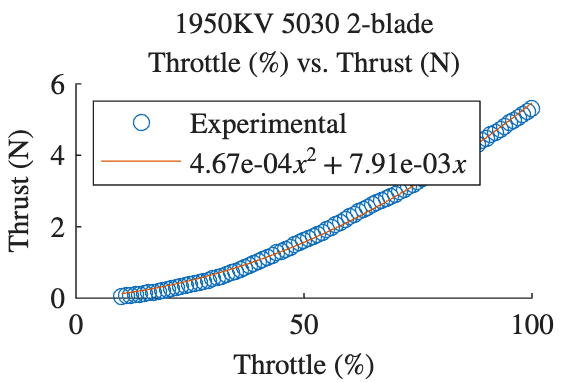

figureWidth = 8; % cm (max. 15)
figureRatio = 0.65; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

figure, hold on;
scatter(Throttles,KV1950.b2_i30.Thrust(10:end))
plot(Throttles,Results.KV1950.b2_i30.Throttle2Thrust(Throttles))
legend('Experimental', sprintf("%.2e", Results.KV1950.b2_i30.Throttle2Thrust.p1) + "$x^2 + $" + sprintf("%.2e", Results.KV1950.b2_i30.Throttle2Thrust.p2) + "$x$", "Location","northwest");
% xline(Results.KV1950.b2_i30.HoverThrottle, "Label", string(Results.KV1950.b2_i30.HoverThrottle), "LabelVerticalAlignment", "bottom", "Interpreter", "latex", "LabelOrientation", "horizontal", "HandleVisibility","off")
% yline(HoverThrust,"Label",string(HoverThrust), "LabelHorizontalAlignment", "left", "Interpreter","latex", "HandleVisibility","off")
title({"1950KV 5030 2-blade"}, {"Throttle (\%) vs. Thrust (N)"})
xlabel("Throttle (\%)")
ylabel("Thrust (N)")
% xlim([0 100])
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;

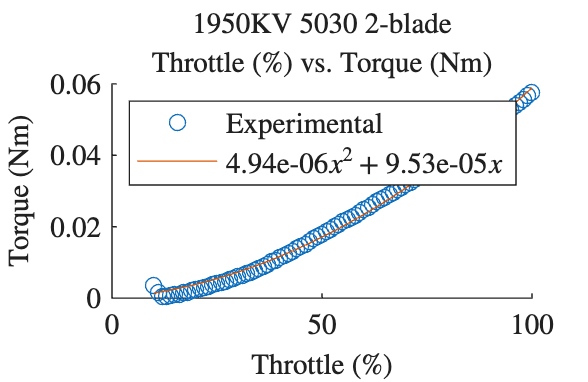


figure, hold on;
scatter(Throttles,KV1950.b2_i30.Torque(10:end))
plot(Throttles,Results.KV1950.b2_i30.Throttle2Torque(Throttles))
legend("Experimental", sprintf("%.2e",Results.KV1950.b2_i30.Throttle2Torque.p1) + "$x^2 + $" + sprintf("%.2e",Results.KV1950.b2_i30.Throttle2Torque.p2) + "$x$", "Location","northwest");
title({"1950KV 5030 2-blade"}, {"Throttle (\%) vs. Torque (Nm)"})
xlabel("Throttle (\%)")
ylabel("Torque (Nm)")
xlim([0 100])
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;

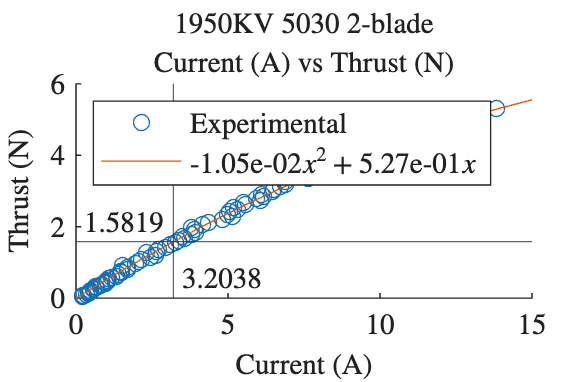


figure, hold on;
scatter(KV1950.b2_i30.Current(10:end), KV1950.b2_i30.Thrust(10:end))
plot(0:15,Results.KV1950.b2_i30.Current2Thrust(0:15))
legend("Experimental", sprintf("%.2e",Results.KV1950.b2_i30.Current2Thrust.p1) + "$x^2 + $" + sprintf("%.2e",Results.KV1950.b2_i30.Current2Thrust.p2) + "$x$", "Location","northwest");
xline(Results.KV1950.b2_i30.HoverCurrent, "Label", string(Results.KV1950.b2_i30.HoverCurrent), "Interpreter", "latex", "LabelOrientation", "horizontal", "HandleVisibility","off", "LabelVerticalAlignment","bottom")
yline(HoverThrust,"Label",string(HoverThrust), "Interpreter","latex", "HandleVisibility","off", "LabelHorizontalAlignment","left")
title({"1950KV 5030 2-blade"}, {"Current (A) vs Thrust (N)"})
xlabel("Current (A)")
ylabel("Thrust (N)")
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;

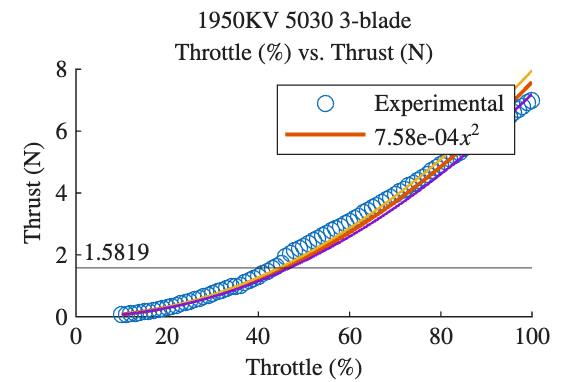



figure, hold on;
scatter(Throttles,KV1950.b3_i30.Thrust(Throttles))
plot(Throttles,Results.KV1950.b3_i30.Throttle2Thrust(Throttles), 'LineWidth',1.5)
plot(Throttles,0.0007581*1.05*(Throttles).^2, 'LineWidth',1)
plot(Throttles,0.0007581*0.95*(Throttles).^2, 'LineWidth',1)
legend('Experimental', sprintf("%.2e", Results.KV1950.b3_i30.Throttle2Thrust.a) + "$x^2$")% + sprintf("%.2e", Results.KV1950.b3_i30.Throttle2Thrust) + "$x$", "Location","northwest");
xline(Results.KV1950.b3_i30.HoverThrottle, "Label", string(Results.KV1950.b3_i30.HoverThrottle), "LabelVerticalAlignment", "bottom", "Interpreter", "latex", "LabelOrientation", "horizontal", "HandleVisibility","off")
yline(HoverThrust,"Label",string(HoverThrust), "LabelHorizontalAlignment", "left", "Interpreter","latex", "HandleVisibility","off")
title({"1950KV 5030 3-blade"}, {"Throttle (\%) vs. Thrust (N)"})
xlabel("Throttle (\%)")
ylabel("Thrust (N)")
xlim([0 100])
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 9);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;


rmse(Results.KV1950.b3_i30.Throttle2Thrust(Throttles), KV1950.b3_i30.Thrust(10:end))

ans = 0.2393

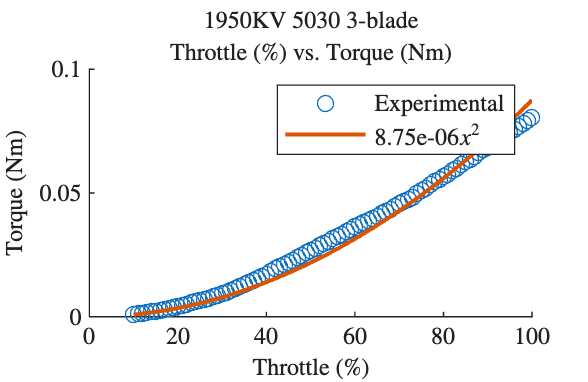


figure, hold on;
scatter(Throttles,KV1950.b3_i30.Torque(Throttles))
plot(Throttles,Results.KV1950.b3_i30.Throttle2Torque(Throttles), 'LineWidth',1.5)
legend("Experimental", sprintf("%.2e",Results.KV1950.b3_i30.Throttle2Torque.a) + "$x^2$")% + sprintf("%.2e",Results.KV1950.b3_i30.Throttle2Torque.p2) + "$x$", "Location","northwest");
xline(Results.KV1950.b3_i30.HoverThrottle, "Label", string(Results.KV1950.b3_i30.HoverThrottle), "LabelVerticalAlignment", "bottom", "Interpreter", "latex", "LabelOrientation", "horizontal", "HandleVisibility","off")
title({"1950KV 5030 3-blade"}, {"Throttle (\%) vs. Torque (Nm)"})
xlabel("Throttle (\%)")
ylabel("Torque (Nm)")
xlim([0 100])
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 9);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;


rmse(Results.KV1950.b3_i30.Throttle2Torque(Throttles),KV1950.b3_i30.Torque(10:end))

ans = 0.0032

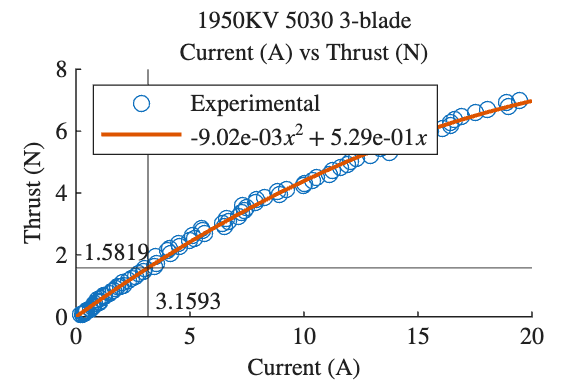


figure, hold on;
scatter(KV1950.b3_i30.Current(10:end), KV1950.b3_i30.Thrust(10:end))
plot(0:20,Results.KV1950.b3_i30.Current2Thrust(0:20), 'LineWidth',1.5)
legend("Experimental", sprintf("%.2e",Results.KV1950.b3_i30.Current2Thrust.p1) + "$x^2 + $" + sprintf("%.2e",Results.KV1950.b3_i30.Current2Thrust.p2) + "$x$", "Location","northwest");
xline(Results.KV1950.b3_i30.HoverCurrent, "Label", string(Results.KV1950.b3_i30.HoverCurrent), "Interpreter", "latex", "LabelOrientation", "horizontal", "HandleVisibility","off", "LabelVerticalAlignment","bottom")
yline(HoverThrust,"Label",string(HoverThrust), "Interpreter","latex", "HandleVisibility","off", "LabelHorizontalAlignment","left")
title({"1950KV 5030 3-blade"}, {"Current (A) vs Thrust (N)"})
xlabel("Current (A)")
ylabel("Thrust (N)")
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 9);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;

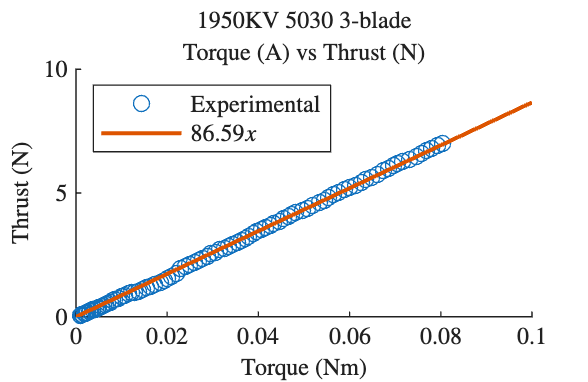


figure, hold on;
scatter(KV1950.b3_i30.Torque(10:end), KV1950.b3_i30.Thrust(10:end))
plot(0:0.01:0.1,Results.KV1950.b3_i30.Torque2Thrust(0:0.01:0.1), 'LineWidth',1.5)
legend("Experimental", sprintf("%.2f",Results.KV1950.b3_i30.Torque2Thrust.p1) + "$x$", "Location","northwest");
title({"1950KV 5030 3-blade"}, {"Torque (A) vs Thrust (N)"})
xlabel("Torque (Nm)")
ylabel("Thrust (N)")
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 9);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off;

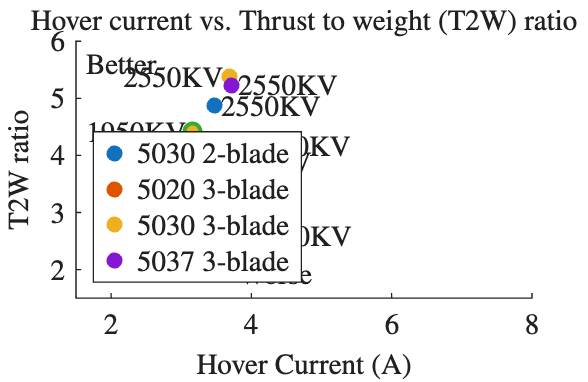

figure, hold on;
datalabeldx = 0.05;
scatter([Results.KV1950.b2_i30.HoverCurrent, Results.KV2550.b2_i30.HoverCurrent], [Results.KV1950.b2_i30.T2WRatio, Results.KV2550.b2_i30.T2WRatio], "filled")
text([Results.KV1950.b2_i30.HoverCurrent+datalabeldx, Results.KV2550.b2_i30.HoverCurrent+datalabeldx], [Results.KV1950.b2_i30.T2WRatio, Results.KV2550.b2_i30.T2WRatio], {"1950KV", "2550KV"}, "horizontalAlignment", "left")
scatter([Results.KV1950.b3_i20.HoverCurrent, Results.KV2550.b3_i20.HoverCurrent], [Results.KV1950.b3_i20.T2WRatio, Results.KV2550.b3_i20.T2WRatio], "filled")
text([Results.KV1950.b3_i20.HoverCurrent+datalabeldx, Results.KV2550.b3_i20.HoverCurrent+datalabeldx], [Results.KV1950.b3_i20.T2WRatio, Results.KV2550.b3_i20.T2WRatio], {"1950KV", "2550KV"})
scatter([Results.KV1950.b3_i30.HoverCurrent, Results.KV2550.b3_i30.HoverCurrent], [Results.KV1950.b3_i30.T2WRatio, Results.KV2550.b3_i30.T2WRatio], "filled")
text([Results.KV1950.b3_i30.HoverCurrent-datalabeldx, Results.KV2550.b3_i30.HoverCurrent-datalabeldx], [Results.KV1950.b3_i30.T2WRatio, Results.KV2550.b3_i30.T2WRatio], {"1950KV", "2550KV"}, "horizontalAlignment", "right")
scatter([Results.KV1950.b3_i37.HoverCurrent, Results.KV2550.b3_i37.HoverCurrent], [Results.KV1950.b3_i37.T2WRatio, Results.KV2550.b3_i37.T2WRatio], "filled")
text([Results.KV1950.b3_i37.HoverCurrent+datalabeldx, Results.KV2550.b3_i37.HoverCurrent+datalabeldx], [Results.KV1950.b3_i37.T2WRatio, Results.KV2550.b3_i37.T2WRatio], {"1950KV", "2550KV"})
text(1.6, 5.9, "Better", "HorizontalAlignment","left","VerticalAlignment","top")
text(4.9, 1.6, "Worse", "HorizontalAlignment","right","VerticalAlignment","bottom")
plot(Results.KV1950.b3_i30.HoverCurrent, Results.KV1950.b3_i30.T2WRatio, 'o', 'LineWidth', 1.5, 'HandleVisibility', 'off');
legend("5030 2-blade", "5020 3-blade", "5030 3-blade", "5037 3-blade", "Location", "southwest")
ylabel("T2W ratio")
xlabel("Hover Current (A)")
title("Hover current vs. Thrust to weight (T2W) ratio")
xlim([1.5 8]);
ylim([1.5 6]);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth*1.2 figureRatio*figureWidth*1.2])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth*1.2 figureRatio*figureWidth*1.2])
hold off


A = [Results.KV1950.b2_i30.MaxThrust Results.KV1950.b2_i30.MaxTorque Results.KV1950.b2_i30.MaxCurrent Results.KV1950.b2_i30.HoverThrottle Results.KV1950.b2_i30.HoverCurrent Results.KV1950.b2_i30.T2WRatio Results.KV1950.b2_i30.PerformanceMetric;...
     Results.KV1950.b3_i20.MaxThrust Results.KV1950.b3_i20.MaxTorque Results.KV1950.b3_i20.MaxCurrent Results.KV1950.b3_i20.HoverThrottle Results.KV1950.b3_i20.HoverCurrent Results.KV1950.b3_i20.T2WRatio Results.KV1950.b3_i20.PerformanceMetric;...
     Results.KV1950.b3_i30.MaxThrust Results.KV1950.b3_i30.MaxTorque Results.KV1950.b3_i30.MaxCurrent Results.KV1950.b3_i30.HoverThrottle Results.KV1950.b3_i30.HoverCurrent Results.KV1950.b3_i30.T2WRatio Results.KV1950.b3_i30.PerformanceMetric;...
     Results.KV1950.b3_i37.MaxThrust Results.KV1950.b3_i37.MaxTorque Results.KV1950.b3_i37.MaxCurrent Results.KV1950.b3_i37.HoverThrottle Results.KV1950.b3_i37.HoverCurrent Results.KV1950.b3_i37.T2WRatio Results.KV1950.b3_i37.PerformanceMetric;...
     Results.KV2550.b2_i30.MaxThrust Results.KV2550.b2_i30.MaxTorque Results.KV2550.b2_i30.MaxCurrent Results.KV2550.b2_i30.HoverThrottle Results.KV2550.b2_i30.HoverCurrent Results.KV2550.b2_i30.T2WRatio Results.KV2550.b2_i30.PerformanceMetric;...
     Results.KV2550.b3_i20.MaxThrust Results.KV2550.b3_i20.MaxTorque Results.KV2550.b3_i20.MaxCurrent Results.KV2550.b3_i20.HoverThrottle Results.KV2550.b3_i20.HoverCurrent Results.KV2550.b3_i20.T2WRatio Results.KV2550.b3_i20.PerformanceMetric;...
     Results.KV2550.b3_i30.MaxThrust Results.KV2550.b3_i30.MaxTorque Results.KV2550.b3_i30.MaxCurrent Results.KV2550.b3_i30.HoverThrottle Results.KV2550.b3_i30.HoverCurrent Results.KV2550.b3_i30.T2WRatio Results.KV2550.b3_i30.PerformanceMetric;...
     Results.KV2550.b3_i37.MaxThrust Results.KV2550.b3_i37.MaxTorque Results.KV2550.b3_i37.MaxCurrent Results.KV2550.b3_i37.HoverThrottle Results.KV2550.b3_i37.HoverCurrent Results.KV2550.b3_i37.T2WRatio Results.KV2550.b3_i37.PerformanceMetric;...
     ];

Results.Table = array2table(A,...
    "VariableNames", {'Max. Thrust', 'MaxTorque', 'Max. Current', 'Hover Throttle', 'Hover Current', 'T2W Ratio', 'T2W by HoverCurrent'}, ...
    'RowNames', {'1950KV 5030 2-blade', '1950KV 5020 3-blade', '1950KV 5030 3-blade', '1950KV 5037 3-blade', '2550KV 5030 2-blade', '2550KV 5020 3-blade', '2550KV 5030 3-blade', '2550KV 5037 3-blade'});
Results.Table

ans = 8×7 table
                           Max. Thrust    MaxTorque    Max. Current    Hover Throttle    Hover Current    T2W Ratio    T2W by HoverCurrent
                           ___________    _________    ____________    ______________    _____________    _________    ___________________

    1950KV 5030 2-blade       5.318       0.057496         13.83             50             3.2038         3.3619             1.0494      
    1950KV 5020 3-blade      4.1027       0.045954        11.375             60             3.9135         2.5936            0.66273      
    1950KV 5030 3-blade      6.9803       0.080454        19.451            -46             3.1593         4.4127             1.3968      

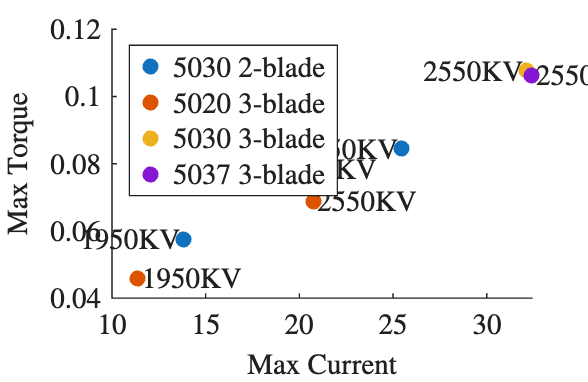

figure, hold on;
datalabeldx = 0.05;
scatter([Results.KV1950.b2_i30.MaxCurrent, Results.KV2550.b2_i30.MaxCurrent], [Results.KV1950.b2_i30.MaxTorque, Results.KV2550.b2_i30.MaxTorque], "filled")
text([Results.KV1950.b2_i30.MaxCurrent-datalabeldx, Results.KV2550.b2_i30.MaxCurrent-datalabeldx], [Results.KV1950.b2_i30.MaxTorque, Results.KV2550.b2_i30.MaxTorque], {"1950KV", "2550KV"}, "horizontalAlignment", "right")
scatter([Results.KV1950.b3_i20.MaxCurrent, Results.KV2550.b3_i20.MaxCurrent], [Results.KV1950.b3_i20.MaxTorque, Results.KV2550.b3_i20.MaxTorque], "filled")
text([Results.KV1950.b3_i20.MaxCurrent+datalabeldx, Results.KV2550.b3_i20.MaxCurrent+datalabeldx], [Results.KV1950.b3_i20.MaxTorque, Results.KV2550.b3_i20.MaxTorque], {"1950KV", "2550KV"})
scatter([Results.KV1950.b3_i30.MaxCurrent, Results.KV2550.b3_i30.MaxCurrent], [Results.KV1950.b3_i30.MaxTorque, Results.KV2550.b3_i30.MaxTorque], "filled")
text([Results.KV1950.b3_i30.MaxCurrent-datalabeldx, Results.KV2550.b3_i30.MaxCurrent-datalabeldx], [Results.KV1950.b3_i30.MaxTorque, Results.KV2550.b3_i30.MaxTorque], {"1950KV", "2550KV"}, "horizontalAlignment", "right")
scatter([Results.KV1950.b3_i37.MaxCurrent, Results.KV2550.b3_i37.MaxCurrent], [Results.KV1950.b3_i37.MaxTorque, Results.KV2550.b3_i37.MaxTorque], "filled")
text([Results.KV1950.b3_i37.MaxCurrent+datalabeldx, Results.KV2550.b3_i37.MaxCurrent+datalabeldx], [Results.KV1950.b3_i37.MaxTorque, Results.KV2550.b3_i37.MaxTorque], {"1950KV", "2550KV"})
legend("5030 2-blade", "5020 3-blade", "5030 3-blade", "5037 3-blade", "Location", "northwest")
ylabel("Max Torque")
xlabel("Max Current")
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off

Battery selection for 1950KV 5030 3-blade

massNoBatt = 0.300*9.81;
battCapacitiesWh = [18 36 53.9 71.9 89.9 107.9 125.8 143.8 161.8];
battCapacitiesmAh = 1000*battCapacitiesWh/14.8;
battWeights = [127 255 382 510 637 765 892 1020 1147]*9.81/1000;
hoverThrusts = (massNoBatt+battWeights)/4;
T2WRatios = max(Results.KV1950.b3_i30.MaxThrust)./hoverThrusts;
for i=1:length(hoverThrusts)
    P_total_hover(i) = (fzero(@(x) feval(Results.KV1950.b3_i30.Current2Thrust, x)-hoverThrusts(i), 0))*4*14.8;
end
flightTimes = 60*battCapacitiesWh./P_total_hover

flightTimes =     8.8969   13.5340   16.2966   18.0790   19.2937   20.1025   20.6515   21.0069   21.2347


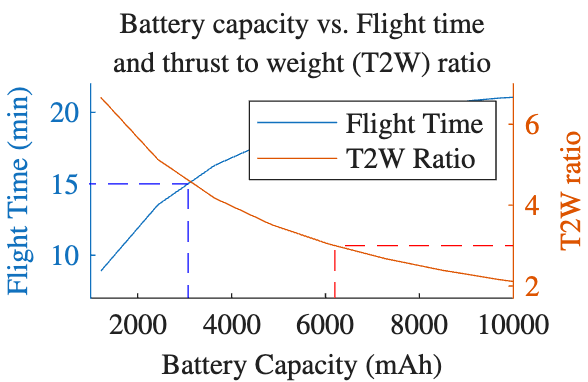


figure, hold on;
xlim([1000 10000])
title({"Battery capacity vs. Flight time"}, {"and thrust to weight (T2W) ratio"})
yyaxis left
plot(battCapacitiesmAh,flightTimes)
plot([0 3074], [15 15], "--", "Color", "blue", "HandleVisibility","off")
plot([3074 3074], [0 15], "--", "Color", "blue", "HandleVisibility","off")
ylim([7 22])
ylabel("Flight Time (min)")
xlabel("Battery Capacity (mAh)")
yyaxis right
plot(battCapacitiesmAh,T2WRatios)
plot([1.094*10^4 6199], [3 3],"--","color","red", "HandleVisibility","off")
plot([6199 6199], [0 3],"--","color","red", "HandleVisibility","off")
ylim([1.7 7])
ylabel("T2W ratio")
legend("Flight Time", "T2W Ratio", "Location", "northeast")

set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])
hold off